# Introduction to Synthetic Aperture Radar Using Python and MATLAB

## by Andy Harrison - © 2022 Artech House

### Example 2.12.13 Spotlight SAR Signal-to-Noise Ratio

## Calculate the signal-to-noise ratios

$\textrm{SNR}=\frac{P_{t\;} A_e^2 \;\sigma \;}{4\pi \;\lambda^2 \;r^4 \;k\;T_{0\;} F\;L}$   Equation (2.42)

${\textrm{SNR}}_{\textrm{image}} =\frac{P_{t\;} A_e^2 \;\sigma \;L_{\textrm{sa}\;} \textrm{PRF}\;}{4\pi \;\lambda^2 \;r^4 \;k\;T_{0\;} F\;L_{\textrm{total}} \;v}$   Equation (2.42)

% Clear the workspace
clear

% Average transmitted power (W)
average_power = 1e3;

% Antenna effective aperture (m^2)
effective_aperture = 0.5;

% Target radar cross section (m^2)
rcs = 0.1;

% Pulsewidth (s)
pulsewidth = 10e-6;

% Operating frequency (Hz)
operating_frequency = 12e9;

% Synthetic aperture length (m)
aperture_length = 500;

% System temperature (K)
system_temperature = 290;

% Receiver bandwidth (Hz)
receiver_bandwidth = 100e6;

% Pulse repetition frequency (Hz)
prf = 10;

% Noise figure
noise_figure = lin(4);

% Unambiguous range (m)
unambiguous_range = 250e3;

% Platform velocity (m/s)
velocity = 250;

% Slant range to imaging area (m)
slant_range = linspace(1e3, 10e3);

% Losses
loss_system = lin(9);

% Processing losses
loss_processing = lin(12);

% Calculate the wavelength (m)
wavelength = 299792458 / operating_frequency;

% Calculate the signal-to-noise
snr = spotlight_snr(average_power, effective_aperture, rcs, operating_frequency, slant_range, ...
    system_temperature, receiver_bandwidth, noise_figure, loss_system);

% Calculate the signal-to-noise ratio with processing gains
snr_image = spotlight_snr_image(average_power, effective_aperture, rcs, pulsewidth, aperture_length, prf, ...
    operating_frequency, slant_range, system_temperature, noise_figure, loss_system, loss_processing, velocity);

## Plot the results

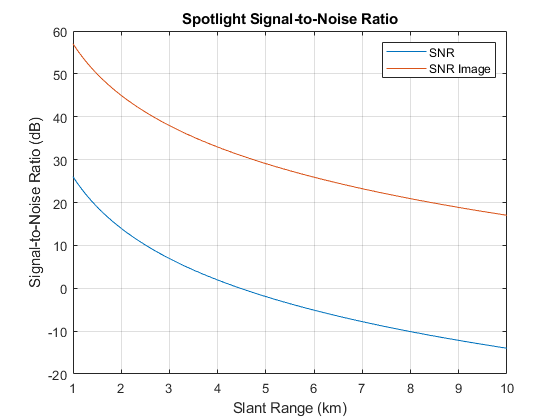

figure;
plot(slant_range/1e3, db(snr)); hold on
plot(slant_range/1e3, db(snr_image))
xlabel('Slant Range (km)')
ylabel('Signal-to-Noise Ratio (dB)');
title('Spotlight Signal-to-Noise Ratio');
legend('SNR', 'SNR Image');
grid on